TF_of_interest = 'CTCF';
load_name = strcat(TF_of_interest, '_positions');
load(load_name)
merged_data

merged_data =            1      237750           1         -13           1
           1      237752           0         -10           1
           1      237762           0         -11           1
           2      521379           1         -14           0
           2      521533           1         -10           1
           2      521535           0          -9           1
           2      521545           0         -11           1
           3      714082           1         -14           0
           3      714183           1         -12           1
           3      714273           0         -11           1


tic
load('chr1shapes')
load('chr1shapes2')
toc

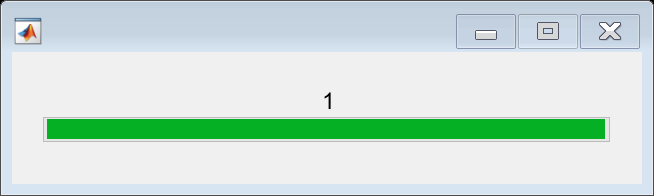

x_data = [];
y_data = [];

success = false;
x = 1;

loading = waitbar(0,'Please wait...');
tic
%length(merged_data)
for i=1:length(merged_data)
    r = i/length(merged_data);
    progress = round(r,5);
    waitbar(progress,loading,string(progress));
 
    C = initial(merged_data(i,2)-3, :);
    C2 = initial2(merged_data(i,2)-3, :);
            
    if merged_data(i,3) == 1
        x_data = [x_data; C C2 merged_data(i, 3) merged_data(i, 4)];
        y_data = [y_data; merged_data(i, 5)];
    else
        C = C';
        idx = reshape(flipud(reshape(1:88,22,4)),1,88);
        C = C(idx,:);
        C = C';
        
        C2 = C2';
        idx = reshape(flipud(reshape(1:88,22,4)),1,88);
        C2 = C2(idx,:);
        C2 = C2';
        
        x_data = [x_data; C C2 merged_data(i, 3) merged_data(i, 4)];
        y_data = [y_data; merged_data(i, 5)];
    end
end

toc

Elapsed time is 6.382727 seconds.



save_name = strcat(TF_of_interest, '_data');
save(save_name, 'x_data', 'y_data')

x_data

x_data =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400   -8.1200   -8.3000   -3.7400   -3.6800   -6.7600   -1.7200   -3.7900   -7.8900   -7.0000   -4.4400   -5.5400   -1.6800   -6.6400   -7.1100   -4.0300   -2.9800   -3.2000   -6.7600   -1.7200   -3.6000   -6.6900   -3.0600   -1.8700    4.3600   -2.0000    3.0800   -0.7300    3.4900
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400   -0.8800   -6.3800   -3.0600   -6.6900   -3.6000   -1.7200   -6.7600   -3.2000   -2.9800   -4.0300   -7.1100   -6.6400   -1.6800   -5.5400   -4.4400   -7.0000   -7.8900   -3.7900   -1.7200   -6.7600   -3.6800   -3.7400   -1.0600   -1.5000    3.9300   -2.1200   -1.9800

y_data

y_data =      1
     1
     1
     0
     1
     1
     1
     0
     1
     1


Arr2 = [x_data y_data]

Arr2 =     5.3200    5.9400    5.9400    5.7900    5.6700    5.2700    5.4300    5.5600    4.8400    5.1900    5.4000    4.5400    4.4200    5.5600    5.4600    5.2400    5.4100    5.6700    5.2700    5.1600    5.7500    5.1400   -8.1200   -8.3000   -3.7400   -3.6800   -6.7600   -1.7200   -3.7900   -7.8900   -7.0000   -4.4400   -5.5400   -1.6800   -6.6400   -7.1100   -4.0300   -2.9800   -3.2000   -6.7600   -1.7200   -3.6000   -6.6900   -3.0600   -1.8700    4.3600   -2.0000    3.0800   -0.7300    3.4900
    4.3700    4.9700    5.1400    5.7500    5.1600    5.2700    5.6700    5.4100    5.2400    5.4600    5.5600    4.4200    4.5400    5.4000    5.1900    4.8400    5.5600    5.4300    5.2700    5.6700    5.7900    5.9400   -0.8800   -6.3800   -3.0600   -6.6900   -3.6000   -1.7200   -6.7600   -3.2000   -2.9800   -4.0300   -7.1100   -6.6400   -1.6800   -5.5400   -4.4400   -7.0000   -7.8900   -3.7900   -1.7200   -6.7600   -3.6800   -3.7400   -1.0600   -1.5000    3.9300   -2.1200   -1.9800  